## 线性回归

clc
clear

x = [143 145 146 147 149 150 153 154 155 156 157 158 159 160 162 164]';
X = [ones(16, 1), x];
Y = [88 85 88 91 92 93 93 95 96 98 97 96 98 99 100 102]';

[b, bint, r, rint, stats] = regress(Y, X, 0.05)  % 线性回归

b =   -16.0730
    0.7194


bint =   -33.7071    1.5612
    0.6047    0.8340


r =     1.2056
   -3.2331
   -0.9524
    1.3282
    0.8895
    1.1702
   -0.9879
    0.2927
    0.5734
    1.8540


rint =    -1.2585    3.6697
   -5.0755   -1.3907
   -3.6086    1.7037
   -1.3085    3.9649
   -1.8718    3.6508
   -1.5750    3.9153
   -3.7915    1.8157
   -2.5680    3.1534
   -2.2676    3.4144
   -0.7730    4.4811


stats =     0.9282  180.9531    0.0000    1.7437


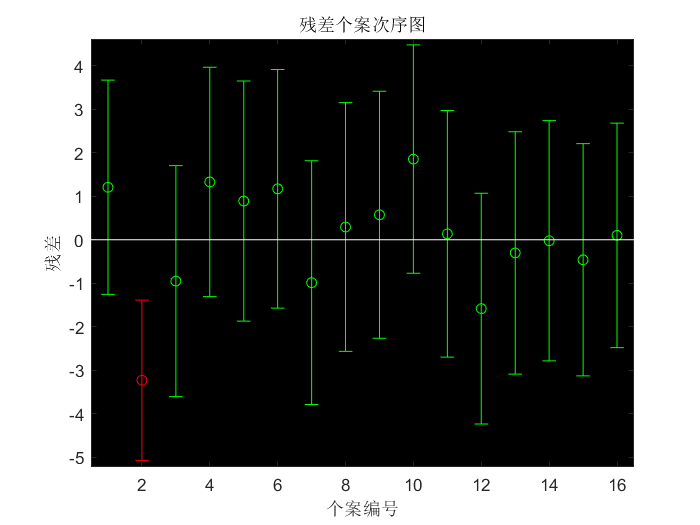


rcoplot(r, rint)  % 残差图

## 二元多项式回归

t = 1/30 : 1/30 : 14/30;
s = [11.86 15.67 20.60 26.69 33.71 41.93 51.13 61.49 72.90 85.44 99.08 113.77 129.54 146.48];
T = [ones(14, 1), t', (t .^ 2)'];

[p, ss] = polyfit(t, s, 2)  % 直接二次多项式回归

p =   489.2946   65.8896    9.1329


ss = 包含以下字段的 struct :
        R: [3×3 double]
       df: 11
    normr: 0.1157



[b, bint, r, rint, stats] = regress(s', T)  % 一次多项式

b =     9.1329
   65.8896
  489.2946


bint =     9.0614    9.2044
   65.2316   66.5476
  488.0146  490.5747


r =    -0.0129
   -0.0302
   -0.0148
    0.0732
    0.0040
    0.0474
   -0.0165
   -0.0078
   -0.0363
   -0.0222


rint =    -0.0704    0.0446
   -0.0964    0.0360
   -0.0885    0.0589
    0.0175    0.1290
   -0.0718    0.0798
   -0.0200    0.1148
   -0.0903    0.0572
   -0.0822    0.0667
   -0.1070    0.0344
   -0.0964    0.0521


stats = 	1.0e+07 *

    0.0000    1.0378    0.0000    0.0000


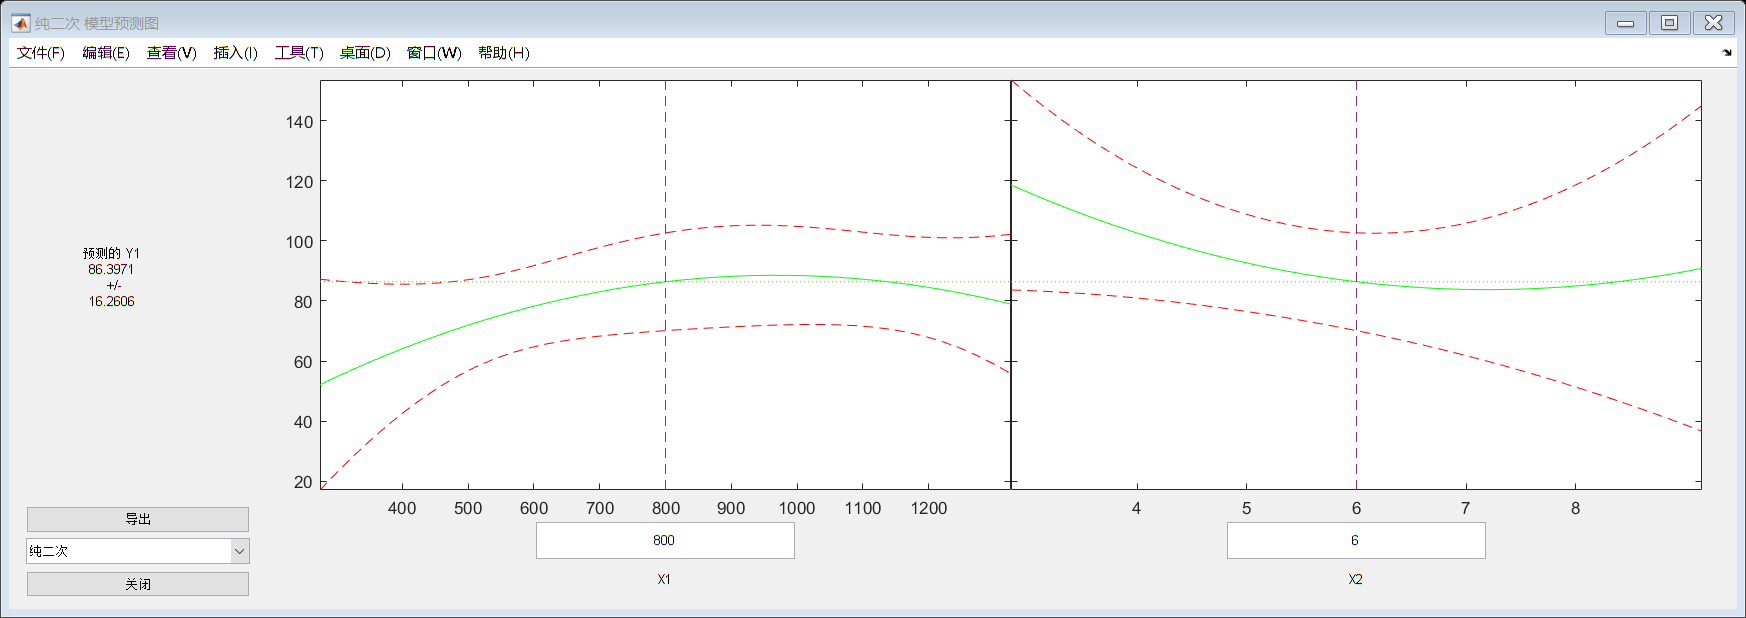

x1 = [1000 600 1200 500 300 400 1300 1100 1300 300];
x2 = [5 7 6 6 8 7 5 4 3 9];
y = [100 75 80 70 50 65 90 100 110 60]';
x = [x1' x2'];
rstool(x, y, 'purequadratic')